## Задание 

Лаб 3. Вы синтезировали регулятор контура тока. Как изменится настройка системы управления, если датчик тока тоже будет измерять ток в мА. Привести формулы для вычисления новых коэффициентов регулятора и графики переходных процессов

Определяем вариант задания:

ob.R = 10+unifrnd(-1,1);
ob.L = 0.02+unifrnd(-0.01,0.01);
ob.J = 100+unifrnd(-10,10);
ob.Ce = 2;
ob.Cm = ob.Ce;
save('data.mat', 'ob');

syms Tu L R s

Передаточная функция электрической части привода постоянного тока

crl.Wob = (1/(L*s+R))/1000;

Передаточная функция разомкнутой системы, настроенной на технический оптиум

Tu = L/R;
crl.Wol = 1/(2*Tu*s*(Tu*s+1))

crl = struct with fields:
    Wob: 1/(1000*(R + L*s))
    Wol: R/(2*L*s*((L*s)/R + 1))
     Tu: 0.0033
    Kia: 1.4541e+06
    Kid: 1.4541e+06
     Tz: 0.0011


передаточная функция регулятора

Wreg = crl.Wol/(crl.Wob);
disp(collect(Wreg, s))

$$\frac{500\,R^{2}}{L\,s}$$

crl.Tu = ob.L/ob.R;
crl.Kia = 500*ob.R/(crl.Tu);
crl.Kid = crl.Kia;
Tmdl = 0.04;

To=0.1*crl.Tu;

Аппроксимация

for i = 1:10
    crl.Tz=i/10*To;
    Tzap(i) = crl.Tz;
    warning off
    warning off
    Simnew = sim('lab3_3_extra.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = Simnew.ia(:,1);
    ia = Simnew.ia(:,3);
    id = Simnew.ia(:,4);
    f(i)=trapz(t,abs(id-ia));

end

Found algebraic loop containing: 
lab3_3_extra/Gain2
lab3_3_extra/Gain4
lab3_3_extra/I tr/Gain6
lab3_3_extra/I tr/Sum2
lab3_3_extra/I tr/Gain5
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0


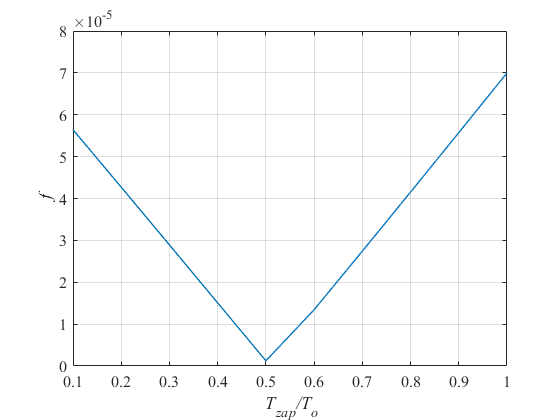

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

### Перенастройка с помощью метода переоборудования

Tmdl = 0.05;
To=1*ob.L/ob.R;
crl.Tz = 0.5*To;
crl.Tu = ob.L/ob.R + crl.Tz

crl = struct with fields:
    Wob: 1/(1000*(R + L*s))
    Wol: R/(2*L*s*((L*s)/R + 1))
     Tu: 0.0018
    Kia: 4.5414e+06
    Kid: 4.5414e+06
     Tz: 6.0167e-04



crl.Kia = 500*ob.R/(crl.Tu);
crl.Kid = crl.Kia;

warning off
simNew = sim('lab3_3_extra.slx', 'ReturnWorkspaceOutputs','on');

Found algebraic loop containing: 
lab3_3_extra/Gain2
lab3_3_extra/Gain4
lab3_3_extra/I tr/Gain6
lab3_3_extra/I tr/Sum2
lab3_3_extra/I tr/Gain5
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3_3_extra/ob1/DC motor/Solver Configuration/EVAL_KEY/OUTPUT_1_0


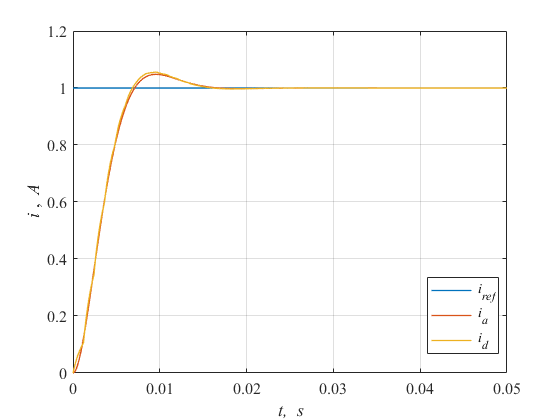

warning on

t = simNew.ia(:,1);
iref = simNew.ia(:,2);
ia = simNew.ia(:,3);
id = simNew.ia(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'Linewidth', 1)
hold on
grid on
plot(t,ia,'Linewidth', 1)
plot(t,id,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it i \rm, \it A')
legend('\it i_{ref}', '\it i_a', '\it i_d','Location','best')

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/crl.Tu)

Время переходного процесса tp2 в 5% зоны: 5.7*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 5.6*Tu 
